## 1)  Generate the basis functions of 1-D and 2-D Fourier transform for the assuemd N of your choice.

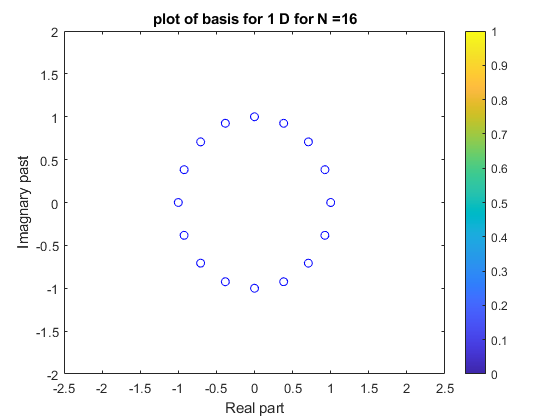

clc; clear all; close all;
N = input('Enter the Number of Points for 1D basis = ');
for k= 1:N
    for n = 1:N
        X(k,n) = exp(-1i*2*pi*(k-1)*(n-1)/N);
    end
%     figure; plot(X(k),'o')
    %plot(real(X(k)),imag(X(k)),'g*')
end
figure; plot(X,'bo')
axis([-2.5 2.5 -2 2])
xlabel('Real part')
ylabel('Imagnary past')
title(['plot of basis for 1 D for N =',num2str(N)]);  colormap("default"); colorbar

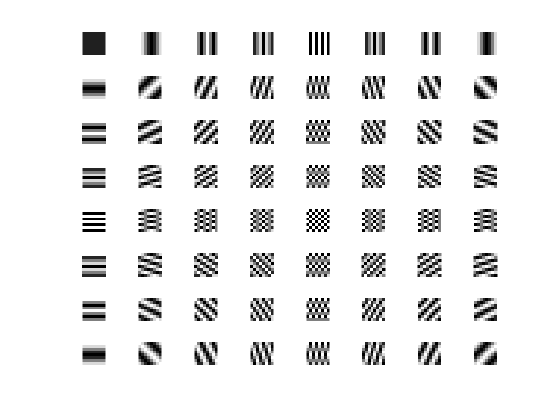

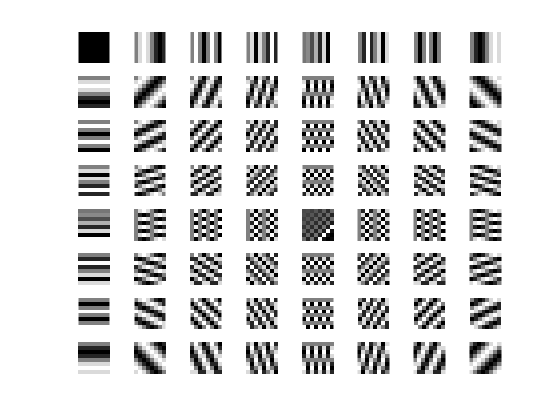

% 2D Basis 
M=8; N=8; [m,n]=meshgrid(0:M-1,0:N-1);
c=1/sqrt(M*N);
figure(2); title('Real Part of Basis of 2D DFT');
figure(3); title('Imagnary Part of Basis of 2D DFT');
for k1=1:M
    for k2=1:N
        k=k1-1; l=k2-1;
        H=exp(1j*2*pi*((k*n/M)+(l*m/N)));
        R=real(c*H);
        figure(2); subplot(M,N,M*(k1-1)+k2);
        imshow(R,[]);
        I=imag(c*H);
        figure(3); subplot(M,N,M*(k1-1)+k2);
        imshow(I,[]);
    end
end

## 2) Obtain the Fourier transform pairs for the following images

### (i) Rectangle centered at the orgin

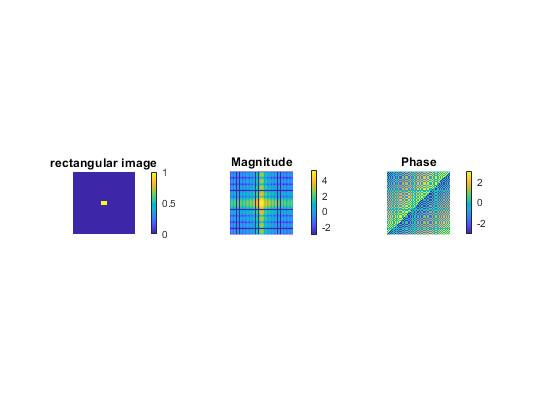

I=zeros(200,200);
I(96:105,91:110)=1; % 10 rows and 20 columns value assigned 
S=fftshift(fft2(I));  % Calculating Fourier Transform
mag = abs(S); pha = angle(S); % Magnitude and Phase of Image 
figure; subplot(131); imshow(I); title('rectangular image'); 
subplot(132); imshow(log(double(mag)),[]); title('Magnitude'); 
subplot(133); imshow(pha, []); title('Phase');  colormap("default");

### (ii) Gaussian function

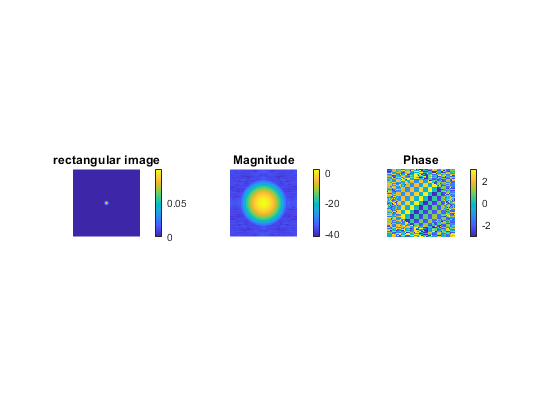

N=256; [x,y]= meshgrid(0:N,0:N); xc=128; yc=128; sigma=4;
Ic=(1/(sigma*sqrt(2*pi)))*exp(-((x-xc).^2+(y-yc).^2)/(2*(sigma)^2)); %gaussian function
Sc=fftshift(fft2(Ic));  % Calculating Fourier Transform
mag = abs(Sc); pha = angle(Sc); % Magnitude and Phase of Image 
figure; subplot(131); imshow(Ic, []); title('rectangular image'); 
subplot(132); imshow(log(double(mag)),[]); title('Magnitude'); 
subplot(133); imshow(pha, []); title('Phase');  colormap("default"); 

### (iii) Circular disk of unit height and raduis ’a’ on origin

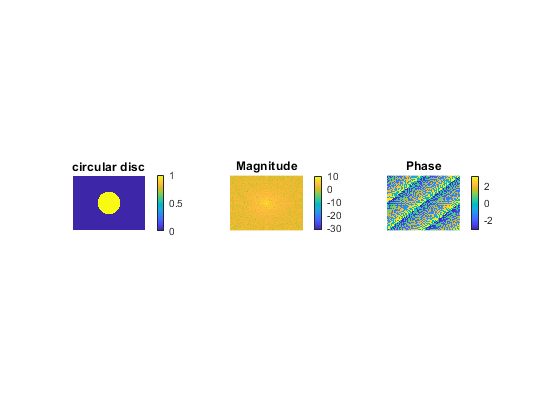

m = 640; n = 480; [c, r] = meshgrid(1:m, 1:n);
% create the circle in the image.
c1 = 320; c2 = 240; radius = 100;
cir = (r - c2).^2 + (c - c1).^2 <= radius.^2;
Sc=fftshift(fft2(cir));  % Calculating Fourier Transform
mag = abs(Sc); pha = angle(Sc); % Magnitude and Phase of Image 
figure; subplot(131); imshow(cir, []); title('circular disc'); 
subplot(132); imshow(log(double(mag)),[]); title('Magnitude'); 
subplot(133); imshow(pha, []); title('Phase'); colormap("default"); 

### (iv) 2-D impluse

x = zeros(200,200); x(100,100)= 1;
Sc=fftshift(fft2(x));  % Calculating Fourier Transform
mag = abs(Sc); pha = angle(Sc); % Magnitude and Phase of Image 
figure; subplot(131); imshow(x, []); title('circular disc'); 
subplot(132); imshow(log(double(mag)),[]); title('Magnitude'); 
subplot(133); imshow(pha, []); title('Phase'); colormap("default"); 

## 3) Show the importance of phase information of Fourier transform with any two images of your choice.

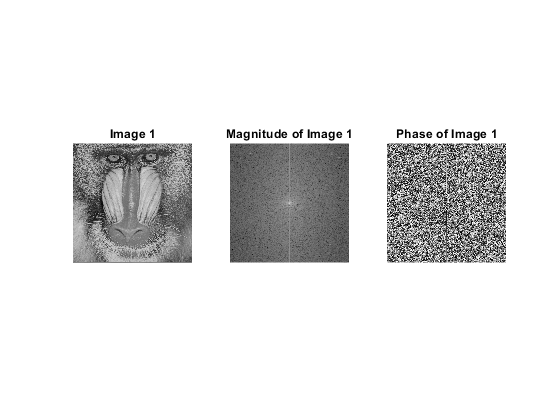

I1 = imread("standard_test_images\baboon.png"); % Reading First Image
I1 = rgb2gray(I1); % Converting from RGB to Gray scale image.
S1=fftshift(fft2(I1));  % Calculating Fourier Transform Image 1
mag1 = abs(S1); pha1 = angle(S1); % Magnitude and Phase of Image 1
figure; subplot(131); imshow(I1); title ("Image 1"); % Plotting Image.
subplot(132); imshow(log(double(mag1)),[]); title('Magnitude of Image 1');
subplot(133); imshow(pha1, []); title ("Phase of Image 1"); % Plotting Image.

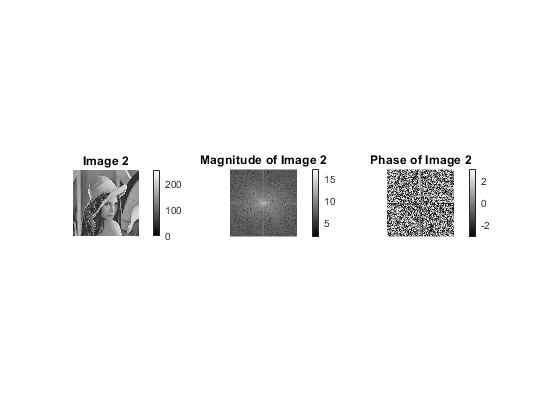

I2 = imread("lenna.bmp"); % Reading Second Image
I2 = rgb2gray(I2); % Converting from RGB to Gray scale image.
S2=fftshift(fft2(I2)); %  % Calculating Fourier Transform Image 2
mag2 = abs(S2); pha2 = angle(S2); % Magnitude and Phase of Image 2
figure; subplot(131); imshow(I2); title ("Image 2");  % Plotting Image.
subplot(132); imshow(log(double(mag2)), []); title ("Magnitude of Image 2"); % Plotting Image.
subplot(133); imshow(pha2, []); title ("Phase of Image 2");% Plotting Image.

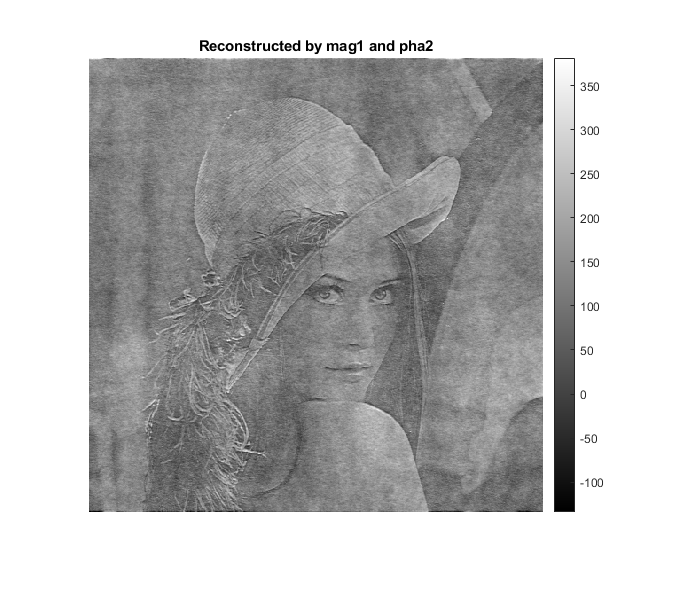

S12 = mag1 .* exp(1j*pha2);% image cross magnitude of A with phase of B
I12 = real(ifft2(fftshift(S12))); %Two-dimensional inverse discrete Fourier transform.
figure; imshow(I12, []); title("Reconstructed by mag1 and pha2"); colorbar;

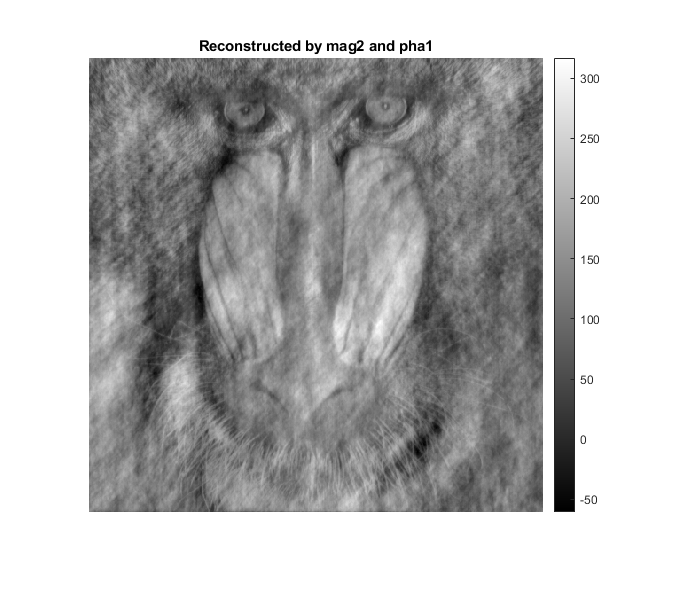

S21 = mag2 .* exp(1j*pha1); % image cross magnitude of A with phase of B
I21 = real(ifft2(fftshift(S21))); %Two-dimensional inverse discrete Fourier transform.
figure; imshow(I21, []); title("Reconstructed by mag2 and pha1"); colorbar;

4) Show the effect of rotating an image by 90� on the magnitude and phase spectrums of the image.

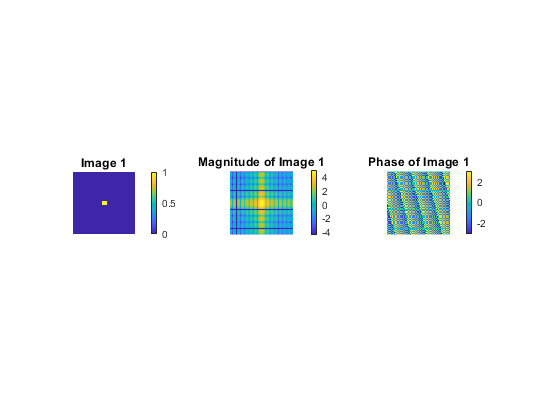

I1=zeros(200,200); % Creating Image 1
I1(96:105,96:110)=1;
S1=fftshift(fft2(I1));  % Calculating Fourier Transform Image 1
mag1 = abs(S1); pha1 = angle(S1); % Magnitude and Phase of Image 1
figure; subplot(131); imshow(I1); title ("Image 1"); % Plotting Image.
subplot(132); imshow(log(double(mag1)),[]); title('Magnitude of Image 1');
subplot(133); imshow(pha1, []); title ("Phase of Image 1");% Plotting Image.
colormap("default");

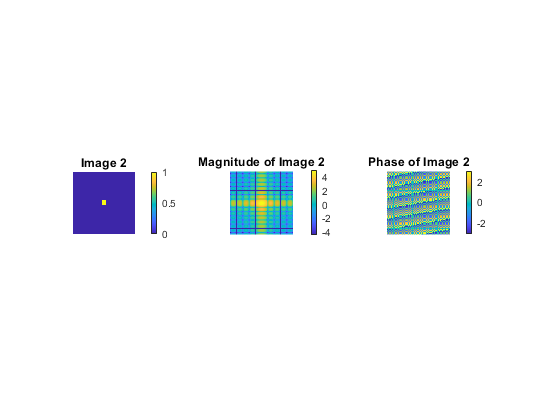

I2 = rot90(I1); % Rotating by 90 degree
S2=fftshift(fft2(I2)); %  % Calculating Fourier Transform Image 2
mag2 = abs(S2); pha2 = angle(S2); % Magnitude and Phase of Image 2
figure; subplot(131); imshow(I2); title ("Image 2");  % Plotting Image.
subplot(132); imshow(log(double(mag2)), []); title ("Magnitude of Image 2"); % Plotting Image.
subplot(133); imshow(pha2, []); title ("Phase of Image 2"); % Plotting Image.
colormap("default"); 

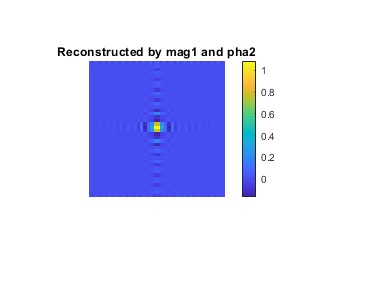

S12 = mag1 .* exp(1j*pha2);% image cross magnitude of A with phase of B
I12 = real(ifft2(fftshift(S12))); %Two-dimensional inverse discrete Fourier transform.
figure; imshow(I12, []); title("Reconstructed by mag1 and pha2"); colormap("default"); colorbar

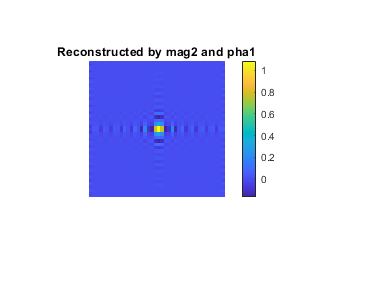

S21 = mag2 .* exp(1j*pha1); % image cross magnitude of A with phase of B
I21 = real(ifft2(fftshift(S21))); %Two-dimensional inverse discrete Fourier transform.
figure; imshow(I21, []); title("Reconstructed by mag2 and pha1"); colormap("default"); colorbar

5) Consider an image (x(n1; n2)) of size N �N and moving average filter of size M �M as impulse

sequence (h(n1; n2)), perform the Convolution and find the response with

(i) Overlap-add method

(ii) Overlap-save method

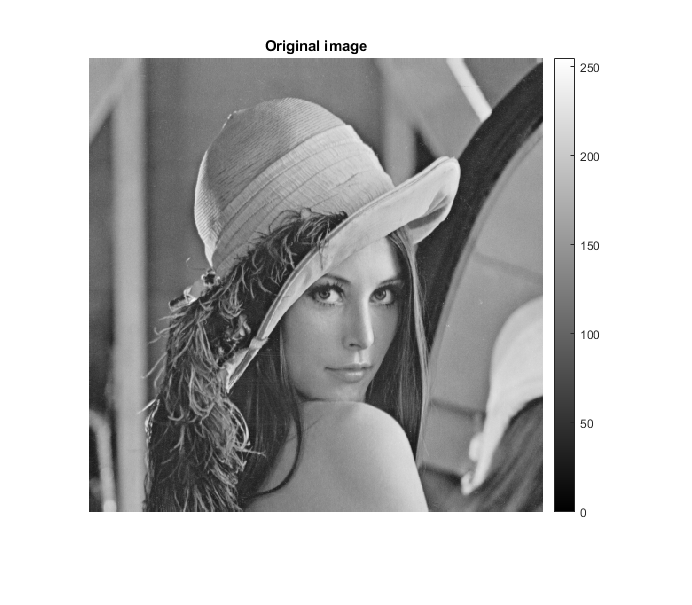

I=imread('lenna.bmp'); [n1, n2]=size(I); % Reading First Image
I=im2gray(I); % Converting from RGB to Gray scale image.
figure; imshow(I); title('Original image'); colorbar; % Plotting Original Image

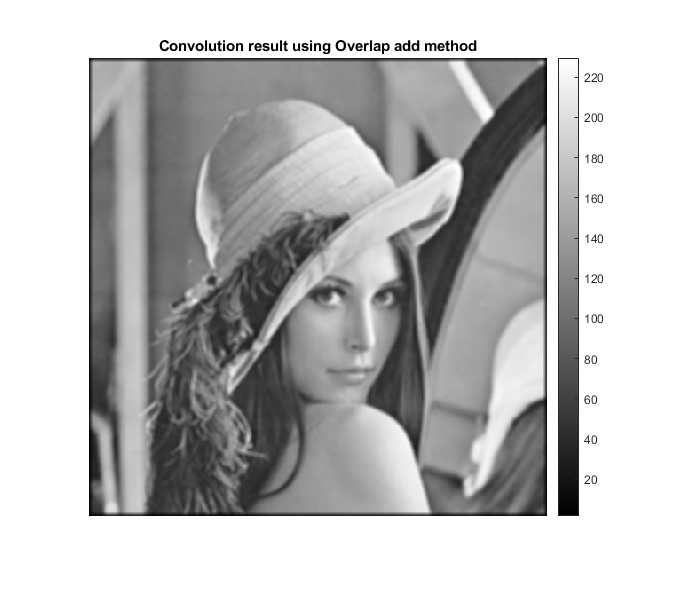


M=input('Enter the size of kernel, M = '); % Creating Kernel 
h=1/(M*M).*(ones(M,M));

s=n1/4;
x11=I(1:s,1:s); x12=I(1:s,s+1:2*s);
x13=I(1:s,2*s+1:3*s); x14=I(1:s,3*s+1:4*s);
x21=I(s+1:2*s,1:s); x22=I(s+1:2*s,s+1:2*s);
x23=I(s+1:2*s,2*s+1:3*s); x24=I(s+1:2*s,3*s+1:4*s);
x31=I(2*s+1:3*s,1:s); x32=I(2*s+1:3*s,s+1:2*s);
x33=I(2*s+1:3*s,2*s+1:3*s); x34=I(2*s+1:3*s,3*s+1:4*s);
x41=I(3*s+1:4*s,1:s); x42=I(3*s+1:4*s,s+1:2*s);
x43=I(3*s+1:4*s,2*s+1:3*s); x44=I(3*s+1:4*s,3*s+1:4*s);
y11=conv2(x11,h); y12=conv2(x12,h);
y13=conv2(x13,h); y14=conv2(x14,h);
y21=conv2(x21,h); y22=conv2(x22,h);
y23=conv2(x23,h); y24=conv2(x24,h);
y31=conv2(x31,h); y32=conv2(x32,h);
y33=conv2(x33,h); y34=conv2(x34,h);
y41=conv2(x41,h); y42=conv2(x42,h);
y43=conv2(x43,h); y44=conv2(x44,h);
z11=padarray(y11,[n1+M-1-length(y11) n1+M-1-length(y11)],'post');
z12=padarray(y12,[n1+M-1-length(y12) n1+M-1-length(y12)],'post');
z12=circshift(z12,[0,s]);
z13=padarray(y13,[n1+M-1-length(y13) n1+M-1-length(y13)],'post');
z13=circshift(z13,[0,2*s]);
z14=padarray(y14,[n1+M-1-length(y14) n1+M-1-length(y14)],'post');
z14=circshift(z14,[0,3*s]);
z21=padarray(y21,[n1+M-1-length(y21) n1+M-1-length(y21)],'post');
z21=circshift(z21,[s,0]);
z22=padarray(y22,[n1+M-1-length(y22) n1+M-1-length(y22)],'post');
z22=circshift(z22,[s,s]);
z23=padarray(y23,[n1+M-1-length(y23) n1+M-1-length(y23)],'post');
z23=circshift(z23,[s,2*s]);
z24=padarray(y24,[n1+M-1-length(y24) n1+M-1-length(y24)],'post');
z24=circshift(z24,[s,3*s]);
z31=padarray(y31,[n1+M-1-length(y31) n1+M-1-length(y31)],'post');
z31=circshift(z31,[2*s,0]);
z32=padarray(y32,[n1+M-1-length(y32) n1+M-1-length(y32)],'post');
z32=circshift(z32,[2*s,s]);
z33=padarray(y33,[n1+M-1-length(y33) n1+M-1-length(y33)],'post');
z33=circshift(z33,[2*s,2*s]);
z34=padarray(y34,[n1+M-1-length(y34) n1+M-1-length(y34)],'post');
z34=circshift(z34,[2*s,3*s]);
z41=padarray(y41,[n1+M-1-length(y41) n1+M-1-length(y41)],'post');
z41=circshift(z41,[3*s,0]);
z42=padarray(y42,[n1+M-1-length(y42) n1+M-1-length(y42)],'post');
z42=circshift(z42,[3*s,s]);
z43=padarray(y43,[n1+M-1-length(y43) n1+M-1-length(y43)],'post');
z43=circshift(z43,[3*s,2*s]);
z44=padarray(y44,[n1+M-1-length(y44) n1+M-1-length(y44)],'post');
z44=circshift(z44,[3*s,3*s]);
overlap=z11+z12+z13+z14+z21+z22+z23+z24+z31+z32+z33+z34+z41+z42+z43+z44;
figure; imshow(overlap,[]); title('Convolution result using Overlap add method'); colorbar;

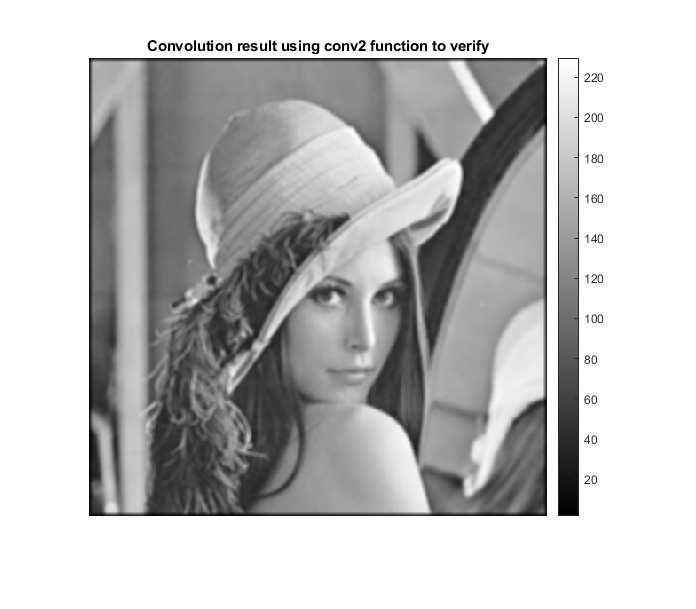

y=conv2(I,h);
figure; imshow(y,[]); title('Convolution result using conv2 function to verify'); colorbar;